% importing data
df1=readtable("../data/experimental-data-1.csv")

df1 = 6×4 table
    dimension    value    uncertainty      uom  
    _________    _____    ___________    _______

     {'d1'}        7.1       0.02        {'MMT'}
     {'d2'}      16.84       0.02        {'MMT'}
     {'d3'}      21.82       0.02        {'MMT'}
     {'d4'}      42.62       0.02        {'MMT'}
     {'F' }         71          1        {'MMT'}
     {'c' }        529          1        {'MMT'}


df2=readtable("../data/experimental-data-2.csv")

df2 = 40×5 table
    index     mass     t5     uncertainty      uom  
    _____    ______    ___    ___________    _______

      1      {'m1'}    8.4        0.6        {'SEC'}
      2      {'m1'}    8.5        0.6        {'SEC'}
      3      {'m1'}    8.7        0.6        {'SEC'}
      4      {'m1'}    8.5        0.6        {'SEC'}
      5      {'m1'}    8.7        0.6        {'SEC'}
      6      {'m1'}    8.5        0.6        {'SEC'}
      7      {'m1'}    8.6        0.6        {'SEC'}
      8      {'m1'}    8.5        0.6        {'SEC'}
      9      {'m1'}    8.7        0.6        {'SEC'}
     10      {'m1'}    8.5        0.6        {'SEC'}
      1      {'m2'}    9.2        0.6        {'SEC'}
      2      {'m2'}    9.2        0.6        {'SEC'}
      3      {'m2'}    9.2        0.6        {'SEC'}
      4      {'m2

tools=readtable("../data/tools.csv")

tools = 3×3 table
             tool              uncertainty      uom  
    _______________________    ___________    _______

    {'Flessometro'        }       0.001       {'MTR'}
    {'Calibro ventesimale'}       2e-05       {'MTR'}
    {'Cronometro'         }         0.6       {'SEC'}



% defining values and converting to SI
d=df1.value(1:4)/1000

d =     0.0071
    0.0168
    0.0218
    0.0426


r=d/2

r =     0.0035
    0.0084
    0.0109
    0.0213


dd=df1.uncertainty(1)/1000

dd = 2.0000e-05

F=table2array(df1(df1.dimension=="F","value"))/1000

F = 0.0710

c=table2array(df1(df1.dimension=="c","value"))/1000

c = 0.5290

mh=unique(df2.mass)

mh = 4×1 cell array
    {'m1'}
    {'m2'}
    {'m3'}
    {'m4'}



T1=table2array(df2(df2.mass=="m1","t5"))/5;
T2=table2array(df2(df2.mass=="m2","t5"))/5;
T3=table2array(df2(df2.mass=="m3","t5"))/5;
T4=table2array(df2(df2.mass=="m4","t5"))/5;

dF=table2array(df1(df1.dimension=="F","uncertainty"))/1000

dF = 1.0000e-03

dc=table2array(df1(df1.dimension=="c","uncertainty"))/1000

dc = 1.0000e-03

dT=df2.uncertainty(2)/5

dT = 0.1200

dr=df1.uncertainty(1)/1000

dr = 2.0000e-05


% average of T
T=[mean(T1);mean(T2);mean(T3);mean(T4)]

T =     1.7120
    1.8400
    1.6760
    1.6920



% creating empty array
g=zeros(length(T),1);
dg=zeros(length(T),1);
cfr=zeros(length(T),1);
re=zeros(length(T),1);
uom=string(zeros(length(T),1));

% calculating curvature radius
R=((c.^2./(8.*F)) + (F./2))

R = 0.5282


for i=1:length(T)
    % gravitational acceleration
    g(i)= ((28*pi^2)*(R-r(i)))/(5*T(i)^2);

    % propagation of error
    dg(i)=((28.*pi.^2)./(5.*T(i).^2)).*(2.*c.*dc)./(8.*F) + abs(1./2 - (c.^2)./(8.*F.^2)).*dF + 28.*pi.^2.*dr./(5*T(i)^2) + (R-r(i))*(2*T(i)*dT)/(5*T(i)^4);

    % uom
    uom(i)="MSK";

    % significant value
    cfr(i)=-floor(log10(dg(i)));
    dg(i)=round(dg(i),cfr(i));
    g(i)=round(g(i),cfr(i));

    % relative error
    re(i)=round((dg(i)./g(i))*100,2);
end

plot1=figure;
plot([0;1;2;3;4;5],[9.81;9.81;9.81;9.81;9.81;9.81])
hold on
errorbar([1;2;3;4],g,dg,dg,'.')
xlim([0,5])
ylim([8,11])
hold off
legend('theoretical','data','Location','southeast')
title('Gravitational acceleration')
ylabel('g (m/s^2)')
xlabel('index')

% creating table
out1=array2table(cat(2,string(mh),g,dg,uom,re),"VariableNames",{'body','gravitational_acceleration','uncertainty','uom','relative_error'})

out1 = 4×5 table
    body    gravitational_acceleration    uncertainty     uom     relative_error
    ____    __________________________    ___________    _____    ______________

    "m1"             "9.89"                 "0.05"       "MSK"        "0.51"    
    "m2"             "8.49"                 "0.04"       "MSK"        "0.47"    
    "m3"             "10.18"                "0.05"       "MSK"        "0.49"    
    "m4"             "9.79"                 "0.05"       "MSK"        "0.51"    


out2=array2table(cat(2,round(mean(g),2),round(mean(dg),2),uom(1),round((round(mean(dg),2)/round(mean(g),2)*100),2)),"VariableNames",{'gravitational_acceleration','uncertainty','uom','relative_error'})

out2 = 1×4 table
    gravitational_acceleration    uncertainty     uom     relative_error
    __________________________    ___________    _____    ______________

              "9.59"                "0.05"       "MSK"        "0.52"    


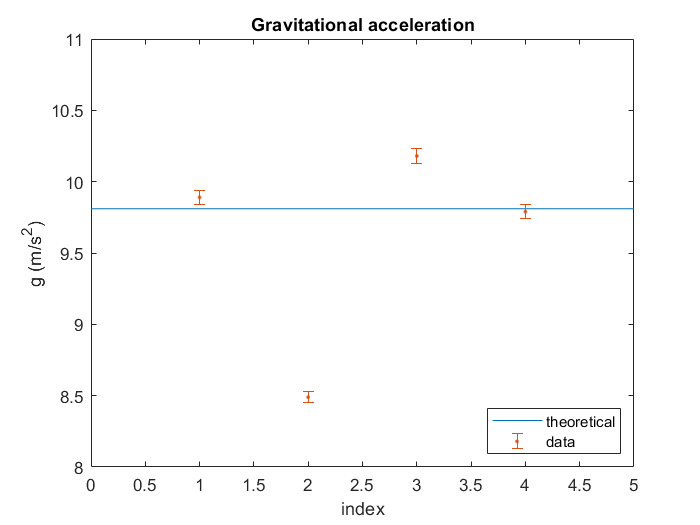


% exporting plot
saveas(plot1,"../img/plot-1.png")


% exporting csv
writetable(out1,"../data/output-data-1.csv","Encoding",'UTF-8','Delimiter',',')
writetable(out2,"../data/output-data-2.csv","Encoding",'UTF-8','Delimiter',',')

% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);